`1. 用升余弦窗设计一线性相位低通FIR 数字滤波器，截止频率``       。窗口长度N=15，33。要求在两种窗口长度情况下，分别求出h(n)，打印出相应的幅频特性和相频特性曲线，观察3dB带宽和20dB 带宽，总结窗口长度N对滤波特性的影响`

N1 = 15; N2 = 33;
wc = pi/4;
M1 = N1 -1 ; M2 = N2 -1 ;
hn1 = fir1(M1 , wc/pi,'low', hanning(N1))   % N1 = 15对应的hn

hn1 =    -0.0012   -0.0077   -0.0137    0.0000    0.0512    0.1341    0.2138    0.2469    0.2138    0.1341    0.0512    0.0000   -0.0137   -0.0077   -0.0012


hn2 = fir1(M2 , wc/pi,'low', hanning(N2))   % N1 = 15对应的hn

hn2 =    -0.0000   -0.0005   -0.0017   -0.0023    0.0000    0.0057    0.0115    0.0113   -0.0000   -0.0205   -0.0383   -0.0360    0.0000    0.0693    0.1536    0.2229    0.2497    0.2229    0.1536    0.0693    0.0000   -0.0360   -0.0383   -0.0205   -0.0000    0.0113    0.0115    0.0057    0.0000   -0.0023   -0.0017   -0.0005   -0.0000


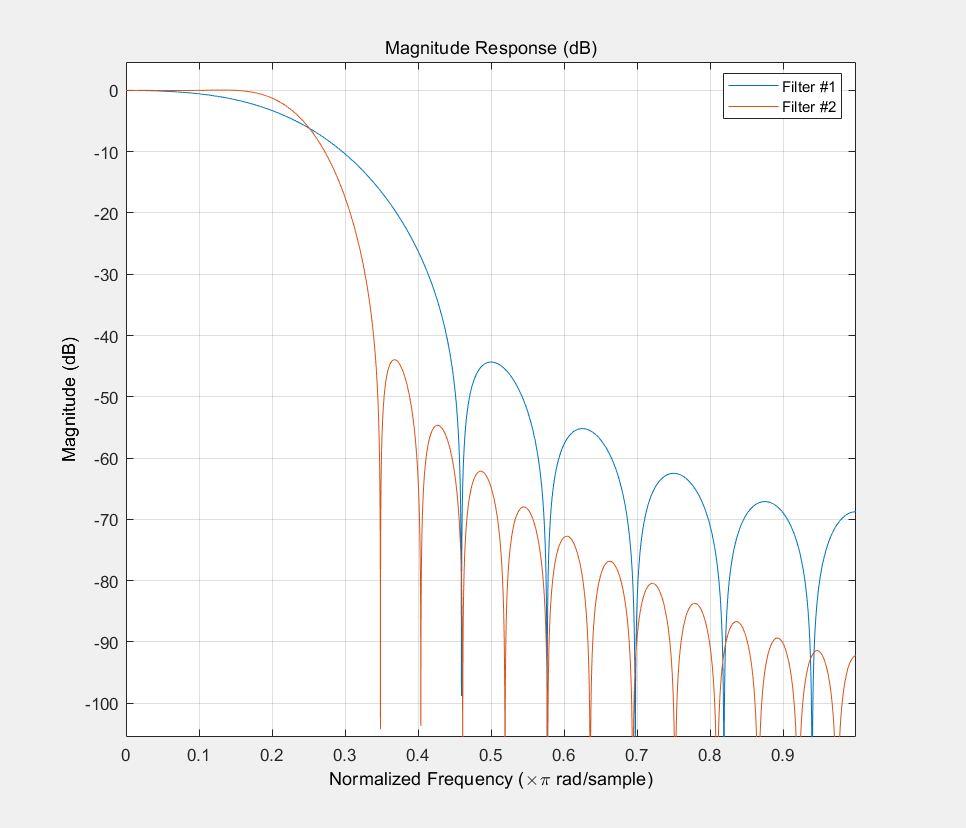


%==========绘制N1=15幅频特性曲线========

hold off;

hfig = fvtool(hn1);   % 双击打游标

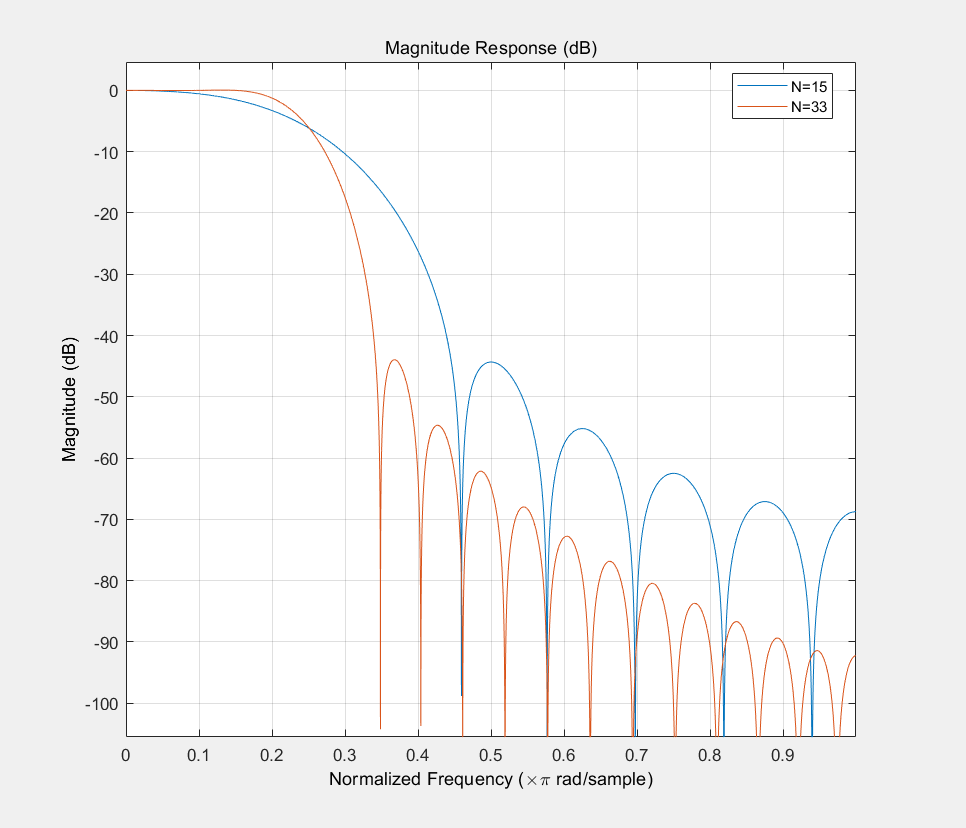


%==========绘制N2=33幅频特性曲线========
%fvtool(hn2);
addfilter(hfig, hn2)
legend(hfig, 'N=15', 'N=33')

N1: 

3dB 带宽: 0.1935   pi

20dB 带宽: 0.3705 pi

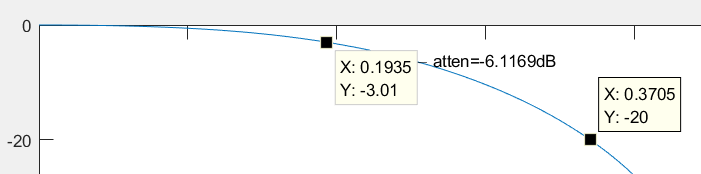

N2: 

3dB 带宽: 0.2244  pi

20dB 带宽: 0.3072 pi

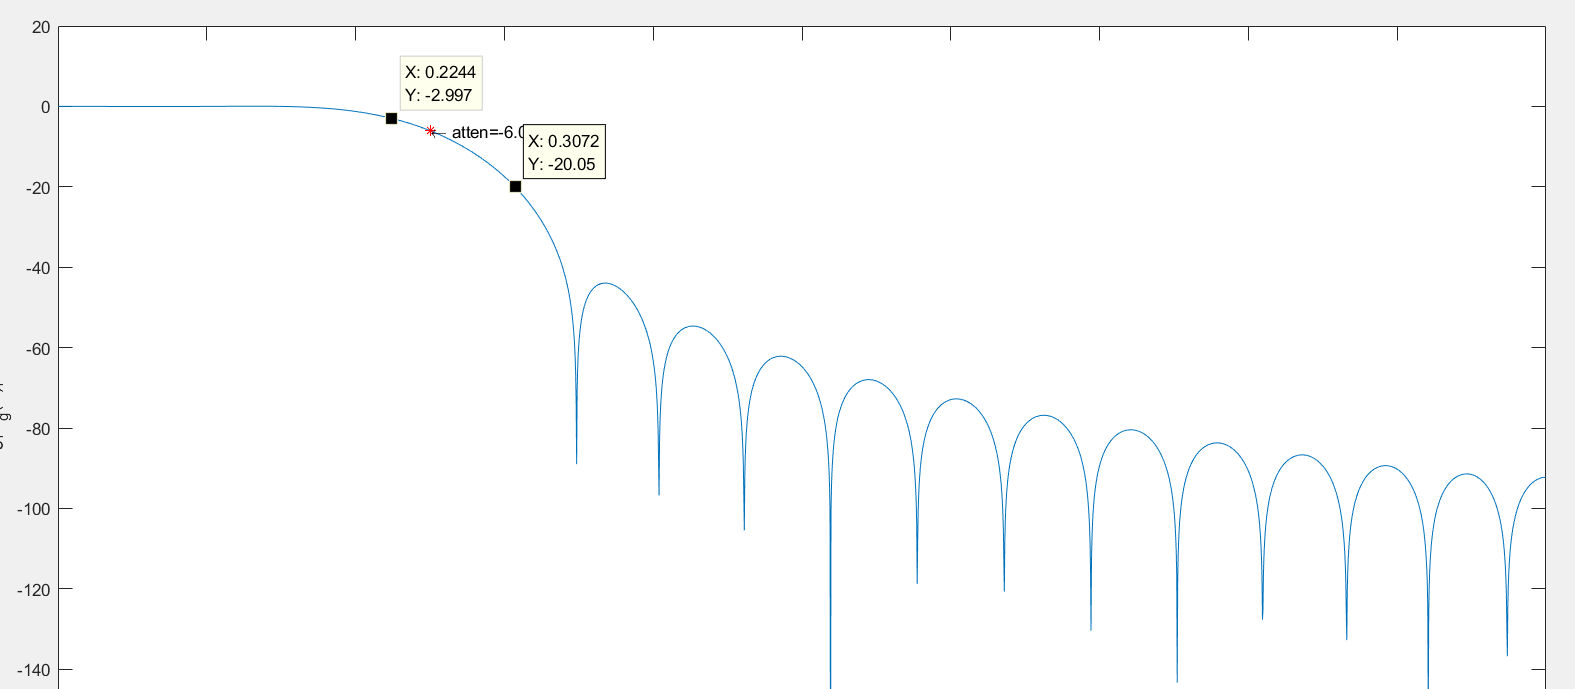

`总结窗口长度N对滤波特性的影响`

`N增大时:`

`过渡带宽度变窄`

`旁瓣变多, 主瓣变窄`

`滤波器更陡`